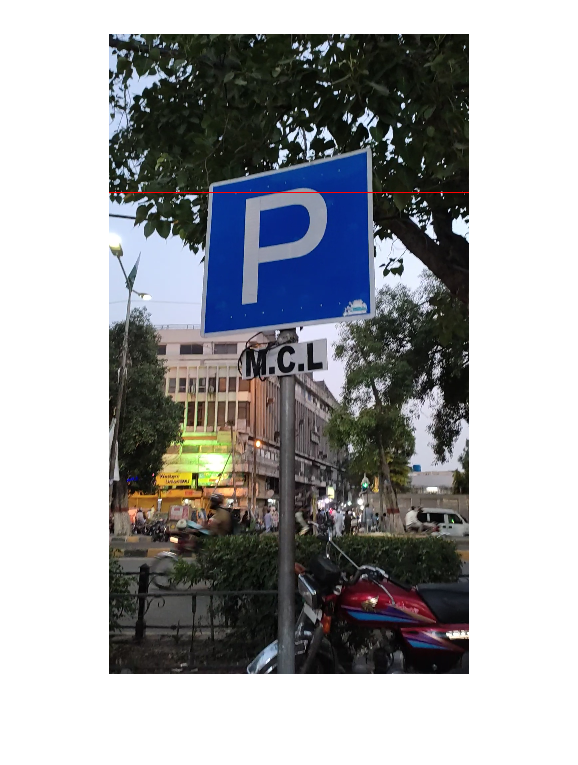

Processing frame 1/159
Processing frame 2/159
Processing frame 3/159
Processing frame 4/159
Processing frame 5/159
Processing frame 6/159
Processing frame 7/159
Processing frame 8/159
Processing frame 9/159
Processing frame 10/159
Processing frame 11/159
Processing frame 12/159
Processing frame 13/159
Processing frame 14/159
Processing frame 15/159
Processing frame 16/159
Processing frame 17/159
Processing frame 18/159
Processing frame 19/159
Processing frame 20/159


% Ask user to select a video
[filename, filepath] = uigetfile({'*.mp4', 'Video files (*.mp4)'}, 'Select a video');
if isequal(filename, 0) || isequal(filepath, 0)
    disp('No video selected. Exiting.');
    return;
end

% Create a VideoReader object
videoPath = fullfile(filepath, filename);
videoReader = VideoReader(videoPath);

% Get the total number of frames in the video
totalFrames = floor(videoReader.Duration * videoReader.FrameRate);

% Create a figure for displaying the live video
figure;

% Process each frame of the video
for frameIndex = 1:totalFrames
    % Read the current frame
    frame = readFrame(videoReader);
    
    % Convert the frame to the LAB color space
    labFrame = rgb2lab(frame);
    
    % Extract the "a" channel which represents color differences
    aChannel = labFrame(:, :, 2);
    
    % Thresholding to segment potential traffic sign regions
    binaryImage = aChannel > 10; % Adjust threshold as needed
    
    % Remove small noise regions
    binaryImage = bwareaopen(binaryImage, 200);
    
    % Perform morphological operations to enhance the regions
    se = strel('disk', 5);
    binaryImage = imclose(binaryImage, se);
    
    % Identify and label connected components
    cc = bwconncomp(binaryImage);
    labeledImage = labelmatrix(cc);
    
    % Calculate the area of each connected component
    area = regionprops(cc, 'Area');
    areaArray = [area.Area];
    
    % Find the largest connected component (assumed to be the traffic sign)
    [~, idx] = max(areaArray);
    
    % Create a mask of the detected traffic sign
    trafficSignMask = labeledImage == idx;
    
    % Calculate the bounding box of the detected traffic sign
    boundingBox = round(expandedBoundingBox); % Rounded to integers
    
    % Draw a red bounding box around the traffic sign
    frameWithBoundingBox = insertShape(frame, 'Rectangle', boundingBox, 'LineWidth', 2, 'Color', 'red');
    
    % Display the frame with bounding box
    imshow(frameWithBoundingBox);
    
    % Print progress
    fprintf('Processing frame %d/%d\n', frameIndex, totalFrames);
    
    % Pause to show the frame (optional)
    pause(0.1);
end% Ask user to select a video

[filename, filepath] = uigetfile({'*.mp4', 'Video files (*.mp4)'}, 'Select a video');
if isequal(filename, 0) || isequal(filepath, 0)
    disp('No video selected. Exiting.');
    return;
end

% Create a VideoReader object
videoPath = fullfile(filepath, filename);
videoReader = VideoReader(videoPath);

% Get the total number of frames in the video
totalFrames = floor(videoReader.Duration * videoReader.FrameRate);

% Create a figure for displaying the live video
figure;

% Process each frame of the video
for frameIndex = 1:totalFrames
    % Read the current frame
    frame = readFrame(videoReader);
    
    % Convert the frame to the LAB color space
    labFrame = rgb2lab(frame);
    
    % Extract the "a" channel which represents color differences
    aChannel = labFrame(:, :, 2);
    
    % Thresholding to segment potential traffic sign regions
    binaryImage = aChannel > 10; % Adjust threshold as needed
    
    % Remove small noise regions
    binaryImage = bwareaopen(binaryImage, 200);
    
    % Perform morphological operations to enhance the regions
    se = strel('disk', 5);
    binaryImage = imclose(binaryImage, se);
    
    % Identify and label connected components
    cc = bwconncomp(binaryImage);
    labeledImage = labelmatrix(cc);
    
    % Calculate the area of each connected component
    area = regionprops(cc, 'Area');
    areaArray = [area.Area];
    
    % Find the largest connected component (assumed to be the traffic sign)
    [~, idx] = max(areaArray);
    
    % Create a mask of the detected traffic sign
    trafficSignMask = labeledImage == idx;
    
    % Get the bounding box of the detected traffic sign
    boundingBox = regionprops(trafficSignMask, 'BoundingBox');
    bb = boundingBox.BoundingBox;
    
    % Add a margin around the bounding box
    margin = 20; % Adjust the margin size as needed
    expandedBoundingBox = [bb(1) - margin, bb(2) - margin, bb(3) + 2*margin, bb(4) + 2*margin];
    
    % Calculate the bounding box of the detected traffic sign
    boundingBox = round(expandedBoundingBox); % Rounded to integers
    
    % Draw a red bounding box around the traffic sign
    frameWithBoundingBox = insertShape(frame, 'Rectangle', boundingBox, 'LineWidth', 2, 'Color', 'red');
    
    % Display the frame with bounding box
    imshow(frameWithBoundingBox);
    
    % Print progress
    fprintf('Processing frame %d/%d\n', frameIndex, totalFrames);
    
    % Pause to show the frame (optional)
    pause(0.1);
end

disp('Video processing complete.');

% Close the figure
close(gcf);


disp('Video processing complete.');

% Close the figure
close(gcf);
